# Assessing the Occurrence of Tularemia in Cottontail Rabbits

*Dr. Eric S. Wright*

*The University of Montana Western*

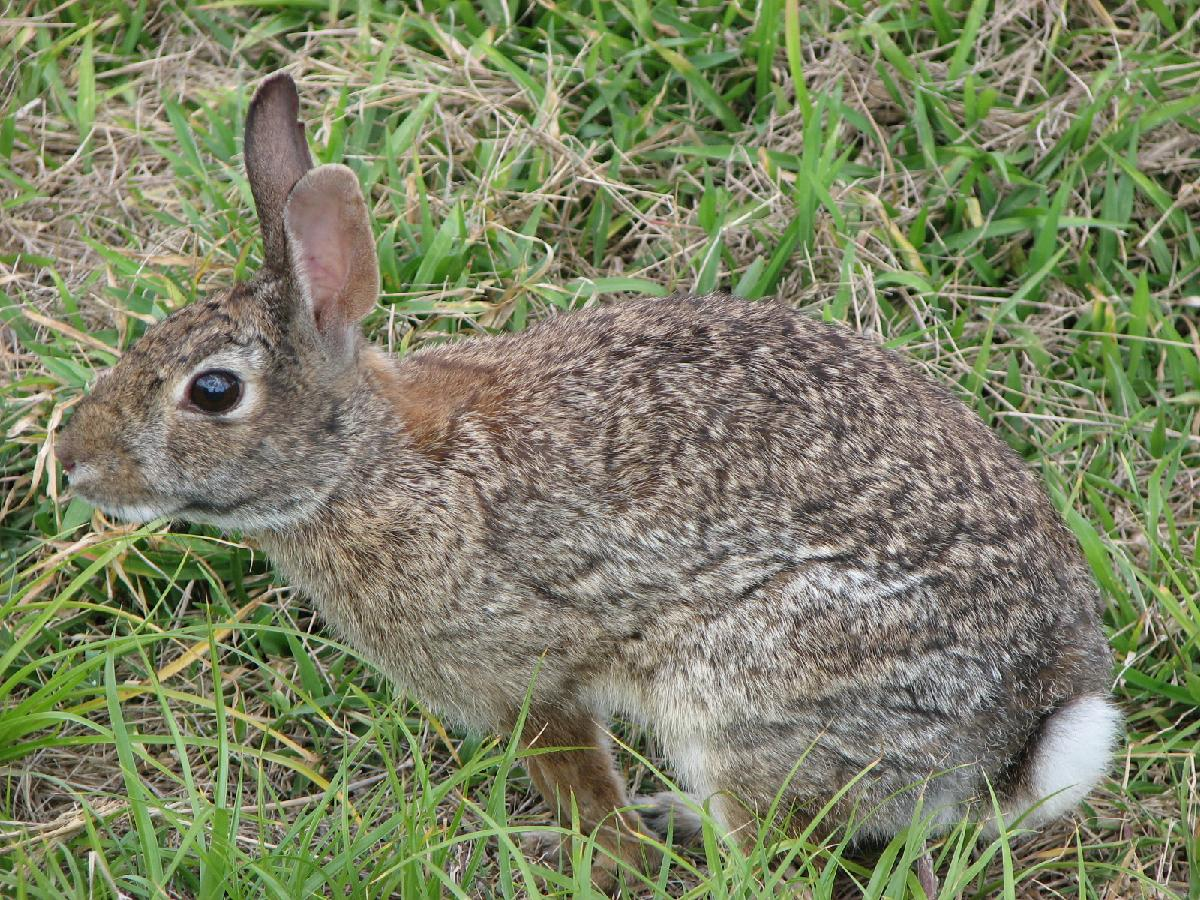

*Image Credit: Dori at English Wikipedia, Public domain, via Wikimedia Commons*

## Introduction

In this LiveScript, we investigate possible causes for differences in the prevalence of Tularemia across different populations of rabbits. In particular, we seek to determine if there is a relationship between climate and Tularemia prevalence. We describe an experiment in which we sample rabbit populations from study sites in both moderate and cold climates, count the number of those rabbits that test positive for Tularemia, and then (through significance testing) determine if there is a significant difference in these counts when comparing those from the moderate climate sites to those from the cold climate sites. *Note: All data for this LiveScript was completely synthetic and was created for demonstration purposes only.*

This program has the following objectives:

- Load external data (both control and experimental) files into MATLAB arrays.

- Compute descriptive statistics of the control data. This will include several measures of central tendency, variability, asymmetry, and the importance of outliers.

- Produce several visualizations of the data including histograms and box and whisker plots.

- Fit a probability distribution to the data using parameter estimation and validate the fit of the model by comparing the relative frequency histogram of the data set to a bar graph of the theoretical distribution, comparing the empirical shape parameters of the data to the theoretical shape parameters of the distribution, examining a quantile-quantile plot, and performing Pearson's goodness of fit test.

- Test the null hypothesis that there is no significant difference between the experimental data and the values our theoretical model for the control data leads us to expect.

- Test the null hypothesis that there is no significant difference between the mean of the experimental data and the expected mean of our theoretical distribution (or that there is no significant difference between the means of the control and experimental data sets).

- Test the null hypothesis that there is no significant difference between the variance of the experimental data and the expected variance of our theoretical distribution (or that there is no significant difference between the variances of the control and experimental data sets).

- Use bootstrap sampling methods and perform tests for differences between means based upon the bootstrap samples. 

## Data Import

Clear all memory, close all figures, and clean out the command line history

clear all; close all; clc;

Since we will be sampling randomly from data sets, choose the seed for the random number generator for reproducibility. Disable this if you want to replicate this experiment multiple times.

rng(1);

Read a control data set containing counts of rabbits diagnosed with tularemia out of 40 different samples of size 30, each taken from a habitat in a moderate climate.

ControlData=csvread('Data/TularemiaControlData.csv');

Read an experimental data set containing counts of rabbits diagnosed with tularemia out of 40 different samples of size 30, each taken from a habitat in a colder climate.

ExperimentalData=csvread('Data/TularemiaExperimentalData.csv');

## Descriptive Statistics

Compute some of the more useful descriptive statistics. 

ds=STAT121utils.descriptiveStats(ControlData)

ds = struct with fields:
         Mean: 11.3500
       Median: 11
         Mode: 11
          Max: 18
          Min: 6
        Range: 12
       StdDev: 2.6977
     Variance: 7.2775
    Quartiles: [9 11 13]
          IQR: 4
     Skewness: 0.4134
       Bowley: 0
     Kurtosis: 2.8657


## Visualization

A histogram summarizes the frequencies of each value found in the control data set.

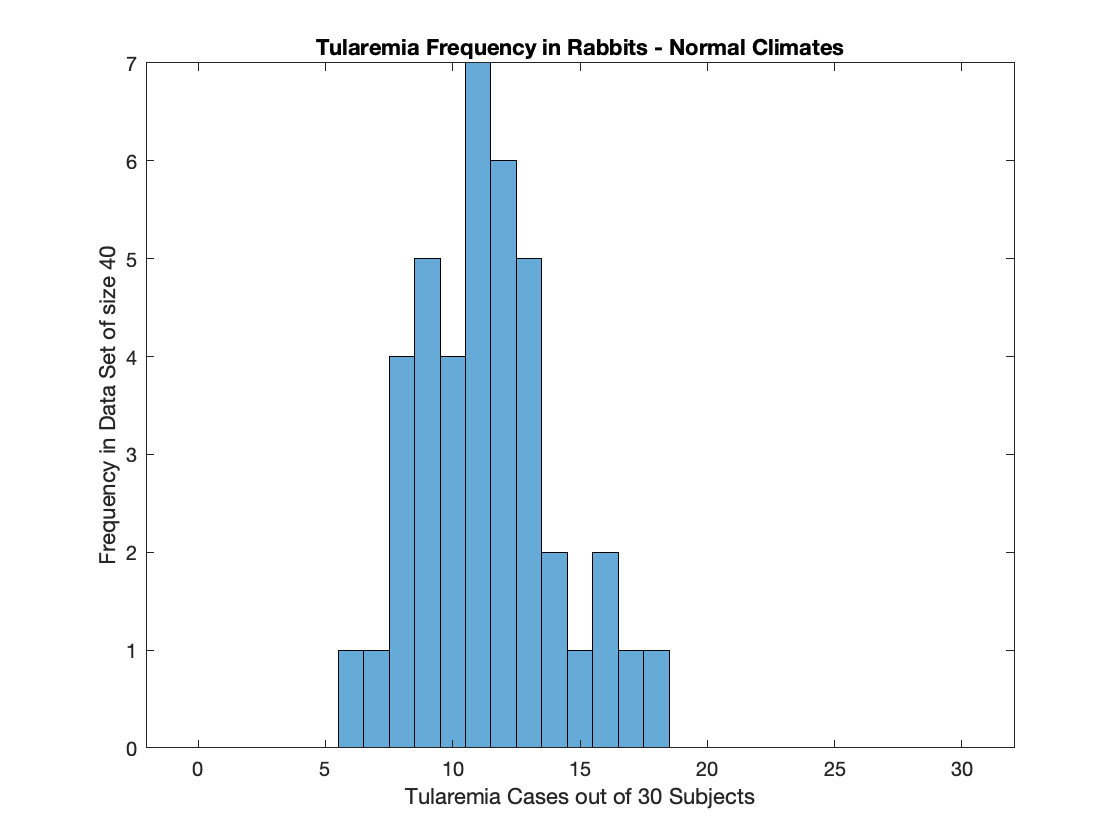

figure(1)
histogram(ControlData,-0.5:1:30.5)
title("Tularemia Frequency in Rabbits - Normal Climates")
xlabel("Tularemia Cases out of 30 Subjects")
ylabel("Frequency in Data Set of size 40")

A box and whisker plot summarizes the quartiles and outliers of the control data set.

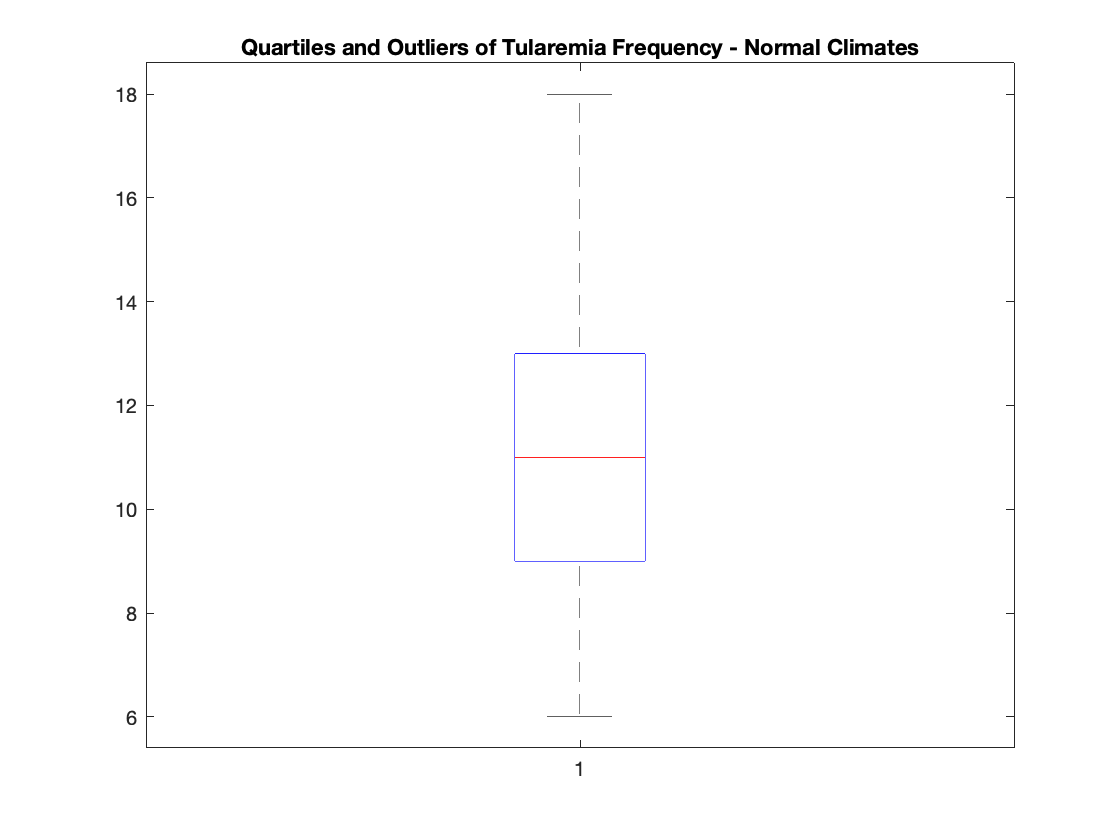

figure(2)
boxplot(ControlData)
title("Quartiles and Outliers of Tularemia Frequency - Normal Climates")

## Parameter Estimation

Ordinarily, we'd estimate the parameters of a probability distribution with maximum likelihood estimation. Unfortunately, this won't work with the hypergeometric distribution, because it has discrete parameters. Instead, we just use mark and recapture based upon the method of moments estimates. Capture and mark a group of $K_0=100$ rabbits, return them to the population, and collect eight samples of $n_0=30$ rabbits. Count the number of marked rabbits ($x_m$) in each sample.

K0=100;
n0=30;
xm=[3,0,2,4,1,1,4,2];

Use the counts of marked rabbits and the method of moments to estimate the total population size by solving the first moment equation: $\bar{x_m}=n_0 \frac{K_0}{N}$ for $N$.

N=n0*K0/mean(xm); 
N=round(N)

N = 1412

With the total population now known, use the control data set and method of monents once more to estimate K by solving the first moment equation $\bar{x_c}=n\frac{K}{N}$ for $K$. Here, $\bar{x_c}$ represents the mean of the control data set.

n=30;
K=mean(ControlData)*N/n;
K=round(K)

K = 534

### Validation

Set the range of your random variable

pd=STAT121utils.HypergeometricDistribution(N,K,n)

pd =   HypergeometricDistribution with properties:

       M: 1412
       K: 534
       N: 30
    mean: 11.3456
     var: 6.9099


Build the arrays of observed frequencies from the control data set and expected frequencies from the theoretical distribution. Compare these frequencies with a side-by-side bar graph.

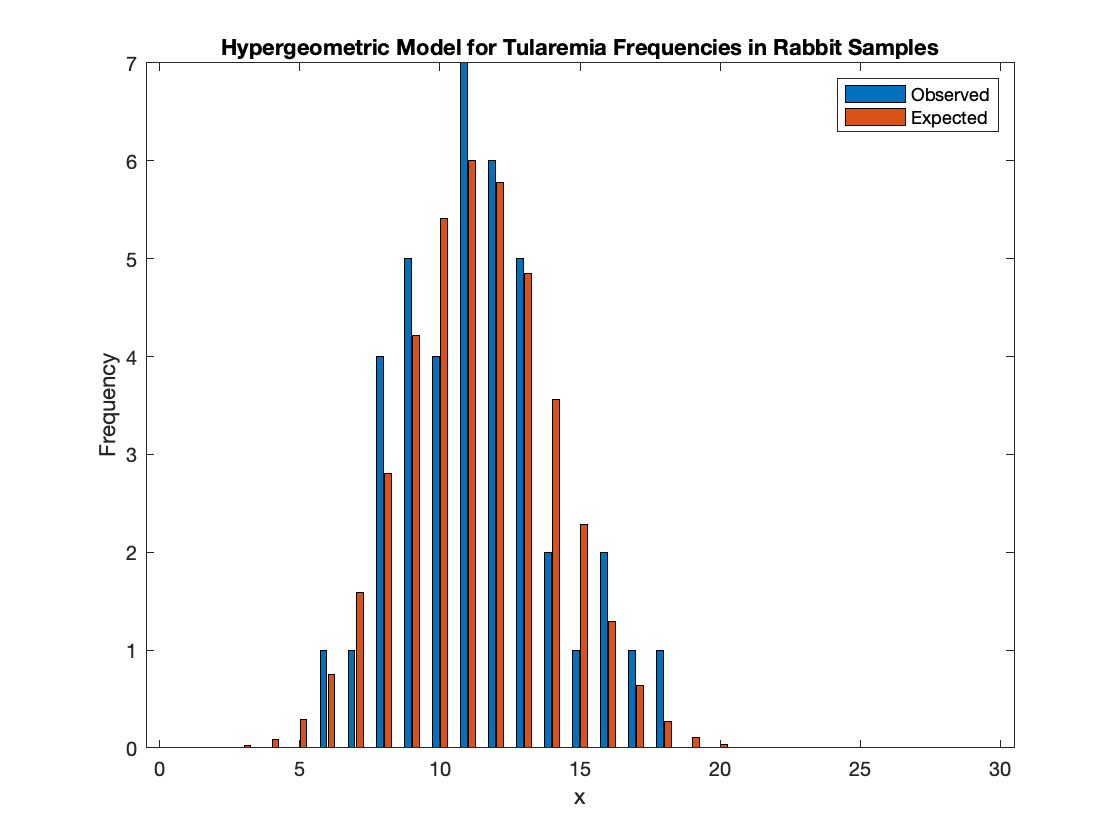

figure(3)
[ObservedFrequencies,ExpectedFrequencies]=STAT121utils.frequencyPlot(ControlData,pd);
title("Hypergeometric Model for Tularemia Frequencies in Rabbit Samples")

Compute and compare the empirical and theoretical shape parameters.

shapes=STAT121utils.compareShapeParameters(ControlData,pd)

shapes = 2×4 table
                    MEAN     VARIANCE    SKEWNESS    KURTOSIS
                   ______    ________    ________    ________

    Empirical       11.35     7.2775      0.41339     2.8657 
    Theoretical    11.346     6.9099     0.088868     2.9436 


Construct a quantile-quantile plot that compares the quantiles of the control data set to the corresponding quantiles of the theoretical distribution. Unfortunately, we can't use the qqplot function in quite the same way with the hypergeometric distribution as we were able to with the other distributions. This is because MATLAB doesn't have a built in HypergeometricDistribution object. We created our own, but there is no reasonable way to make it compatible with the qqplot function (which expects the `ProbabilityDistribution` object to be a part of the `prob` package). One way around this is to just compute the empirical quantiles of the data and the theoretical quantiles of the hypergeometric distribution on our own and feed those to the qqplot function. This works, and is only necessary when working with the hypergeometric distribution.

figure(4)
EmpiricalQuantiles=quantile(ControlData,length(ControlData),'all')

EmpiricalQuantiles =     6.4756
    7.4512
    8.0000
    8.0000
    8.0000
    8.3537
    9.0000
    9.0000
    9.0000
    9.0000



TheoreticalQuantiles=pd.inv((1:length(ControlData))/(length(ControlData)+1))

TheoreticalQuantiles =      6     7     8     8     8     9     9     9     9     9    10    10    10    10    10    11    11    11    11    11    11    12    12    12    12    12    12    13    13    13    13    13    14    14    14    14    15    15    16    17


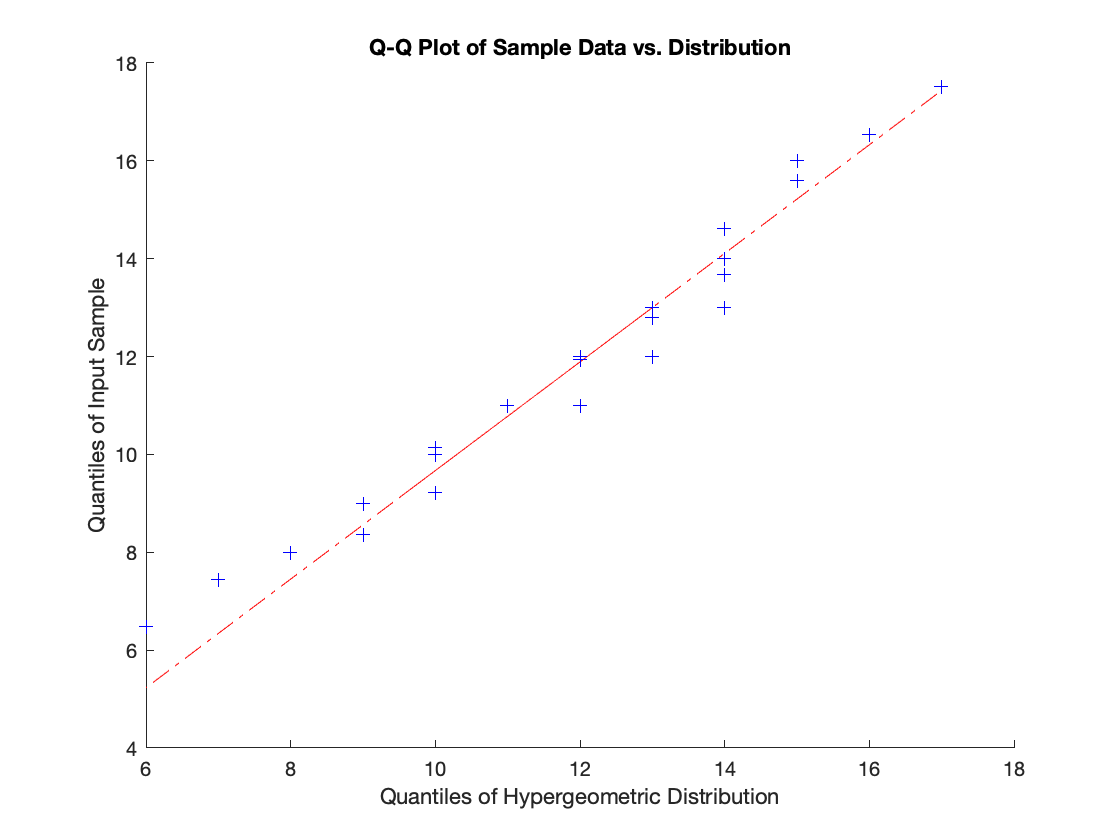

qqplot(TheoreticalQuantiles,EmpiricalQuantiles);
xlabel('Quantiles of Hypergeometric Distribution');
ylabel('Quantiles of Input Sample')
title('Q-Q Plot of Sample Data vs. Distribution')

Finally, perform Pearson's goodness of fit test.

bins=0:30;
[h,pChi2,stats]=chi2gof(ControlData,'Ctrs',bins,'CDF',@pd.cdf,'NParams',2)

h = 0

pChi2 = 0.6755

stats = struct with fields:
    chi2stat: 0.7845
          df: 2
       edges: [-0.5000 9.5000 10.5000 11.5000 12.5000 30.5000]
           O: [11 4 7 6 12]
           E: [9.7590 5.4116 6.0021 5.7794 13.0479]


All of our validation techniques point to a good fit between our hypergeometric model and our control data set.

## Hypothesis Testing 

### Fisher's Significance Testing

#### Hypergeometric Test 

Since we were able to establish such strong validation for the fit between the hypergeometric model and our control data, we are justified in conducting the hypergeometric tests for differences between experimental data and behavior predicted by the model. The null hypothesis for this test is

$H_0$: *We will not observe significantly different numbers of rabbits infected with Tularemia in the cold climate samples than we observe in the other samples.*

The p values resulting from the hypergeometric test are computed as follows:

[pIncreaseDiscrete,pDecreaseDiscrete]=STAT121utils.discreteSignificance(ExperimentalData,pd)

pIncreaseDiscrete =     0.9994
    1.0000
    0.9899
    0.9315
    0.9899
    0.9971
    0.9994
    0.9999


pDecreaseDiscrete =     0.0029
    0.0000
    0.0289
    0.1387
    0.0289
    0.0101
    0.0029
    0.0006


While none of the tests for an increase produced significant results, the majority of the p values we computed in a test for a decrease fell well below 5%. This is strong evidence for rejecting the null hypothesis.

#### One Sample T-Test

The good fit between the hypergeometric model and the control data also provides justification for conduct a one sample t test for differences between the mean of the experimental set and the theoretical means predicted by the hypergeometric distribution. The null hypothesis for this test is

$H_0$: There is no significant difference between the mean of the experimental data set and the theoretical mean predicted by the hypergeometric distribution. This test can be performed as follows:

[h,pt,ci,stats]=ttest(ExperimentalData,pd.mean)

h = 1

pt = 4.5605e-05

ci =     2.8410
    6.4090


stats = struct with fields:
    tstat: -8.9079
       df: 7
       sd: 2.1339


In this case we have a small p value (pt) which signifies strong evidence for rejecting the null hypothesis that the theoretical mean and mean of the experimental sample are the same. The ttest function also provides us with a 95% confidence interval that establishes the location of the true mean for the population that the experimental data is taken from.

#### Two Sample T Test

Alternatively, we could address the slightly different task of determining if there is a difference between the means of the control and experimental data sets by conducting the two sample t test. Before doing so, it is worth investigating the similarity between the control and experimental variances, because this can impact how we design our two sample T test. There are two approaches we can follow:

First, since we know the hypergeometric distribution fits our control data well, we are justified in conducting the $\chi^2$ test for differences between the sample variance of our experimental data set and our theoretical variance predicted by the hypergeometric distribution. The null hypothesis for the $\chi^2$ test is

$H_0$*: There is no significant difference between the variance of the experimental data and the theoretical variance predicted by the hypergeometric distribution.*

and we may perform the test as follows:

[h,pvar,ci,stats]=vartest(ExperimentalData,pd.var)

h = 0

pvar = 0.5859

ci =     1.9906
   18.8624


stats = struct with fields:
    chisqstat: 4.6130
           df: 7


We can se that the p vlaue is too high to reject the null hypothesis that there is no difference between the variances. The $\chi^2$ test also supplies a 95% confidence interval for the true variance of the population the experimental data was sampled from.

If we had been unable to establish such a good fit between our hypergeometric model and our control data, we could alternatively investigate similarities between the variances of the populations the experimental and control data sets were sampled from by conducting the F test. While this is unnecessary in our particular case, we'll still perform it. The null hypothesis for this test is

$H_0$*: There is no significant difference between the variance of the experimental data set and the variance of the control data set. *

We perform the test as follows:

[h,pvar2,ci,stats]=vartest2(ExperimentalData,ControlData)

h = 0

pvar2 = 0.5119

ci =     0.2317
    2.6312


stats = struct with fields:
    fstat: 0.6101
      df1: 7
      df2: 39


Again, the p value is too high to justify rejecting the null hypothesis that there is no difference between the variance. The F test also supplies a 95% confidence interval for the true ratio between the variances of the experimental and control populations.

Both tests allow us to assume that the experimental and control variances are at least somewhat similar. However, the confidence intervals we've computed are also somewhat large, so there is some uncertainty surrounding this assumption. While we are probably still justified in performing the two sample t test with an equal variance assumption in place, it would be more conservative of us to drop that assumption. 

The null hypothesis for the two sample t test (without an assumption of equal variances between the experimental and control samples) is 

$H_0$*: There is no significant difference between the means of the experimental and control data sets.* 

This test bypasses the need of knowing that the hypergeometric distribution is the model for our original infected rabbit counts and having access to the theoretical mean of that distribution. We simply treat our control and experimental data sets as two independent samples (with potentially different sample variances) and test for equality of the two sample means. This would have been an appropriate choice of a hypothesis test for determining differences between our experimental and control measurements had we been unable to achieve a strong fit between our hypergeometric model and the control data. While it is somewhat unnecessary in our case, we may perform this test as follows:

[h,pt2,ci,stats]=ttest2(ExperimentalData,ControlData,"Vartype","unequal")

h = 1

pt2 = 5.0108e-06

ci =    -8.6173
   -4.8327


stats = struct with fields:
    tstat: -7.7355
       df: 12.1084
       sd: [2×1 double]


Again, we have a small p value (pt2) which signifies strong evidence for rejecting the null hypothesis that the means of the experimental and control samples are the same. The ttest2 function also provides us with a 95% confidence interval that establishes the location of the difference between the true means for the populations that the experimental and control data is taken from.

### Bootstrap Methods 

Bootstrap sampling provides us with a way of generating larger, synthetic data sets from our established control and experimental data sets through the practice of resampling. These methods can be used as alternative approaches for determining if there is a significant difference between the experimental and control means. They also completely sidestep the need for assuming that any particular model fits our experimental or control data sets well. Finally, they provide us with confidence intervals that may give us some insight into how our experiment might play out, were we to repeat it multiple times.

#### Bootstrap Confidence Interval

Simulate 2000 samples of 40 data points from the control data set and compute their means. This set of means is a bootstrap data set.

B=2000;
bootstrapMeans=bootstrp(B,@mean,ControlData);

Compute a 95%, two-tailed confidence interval from the bootstrap data set by locating its 2.5 and 97.5 percentiles. Determine where the mean of the experimental data set falls relative to the confidence interval.

CI=quantile(bootstrapMeans,[0.025 0.975])

CI =    10.5375   12.1375


Me=mean(ExperimentalData)

Me = 4.6250

Visualize the confidence interval and experimental mean on top of the bootstrap data set.

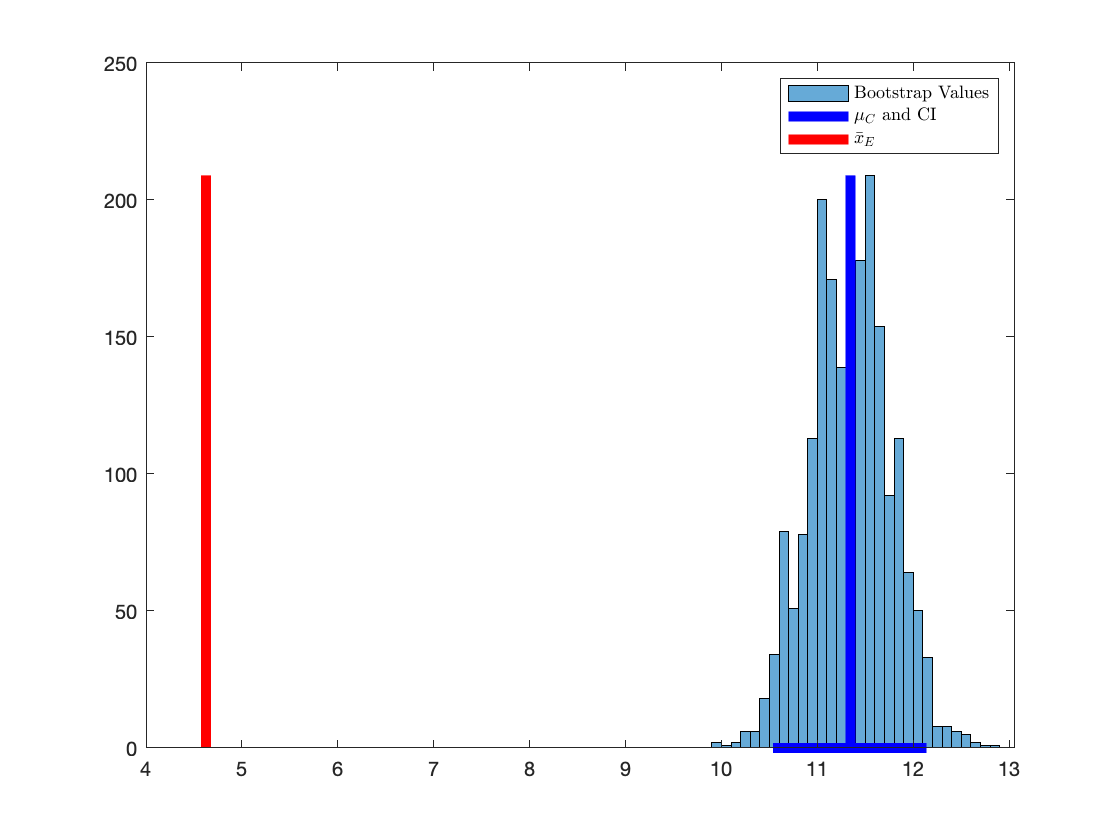

figure(5)
h=histogram(bootstrapMeans);
hold on
plot(CI,[0,0],'b','LineWidth',5)
plot([Me,Me],[0,max(h.BinCounts)],'r','LineWidth',5)
plot([pd.mean,pd.mean],[0,max(h.BinCounts)],'b','LineWidth',5)
legend('Bootstrap Values','$\mu_C$ and CI', '$\bar{x}_E$','interpreter','Latex')
hold off

We can see that the mean of our experimental data set falls well outside of the bootstrap confidence interval. This is an indication that the mean of our experimental data set is quite different from what we expect to see in typical control data.

#### Bootstrap Two Sample Test

We can also create a bootstrap sample from our experimental data set. Our experimental data set is small to begin with, so the information we'll achieve by doing this is a little limited, but it still has the potential to give us a better picture of what might happen should we repeat our experiment multiple times. 

Create 2000 bootstrap samples from both the control and experimental data sets. The size of each sample taken from the control data set should mirror the size of the control data set. The size of each sample taken from the experimental data set should mirror the size of the experimental data set. For each sample, track the sample means and sample standard deviations as well as the two sample t statistic (that makes no assumption about similarity between control and sample variances).

B=2000;

Nc=length(ControlData);
Ne=length(ExperimentalData);
xbar=mean(ControlData);
ybar=mean(ExperimentalData);
zbar=mean([ControlData' ExperimentalData']);
s2x=var(ControlData);
s2y=var(ExperimentalData);
t0=(xbar-ybar)/sqrt(s2x/Nc+s2y/Ne);

statsc=bootstrp(B,@(x)[mean(x),var(x)],ControlData-xbar+zbar);
statse=bootstrp(B,@(x)[mean(x),var(x)],ExperimentalData-ybar+zbar);
Mc=statsc(:,1);
S2c=statsc(:,2);
Me=statse(:,1);
S2e=statse(:,2);
t=(Mc-Me);
t=t./sqrt((S2c/Nc)+(S2e/Ne));

Compare the histograms of the two bootstrap data sets together with their confidence intervals.

figure(6)
CIc=quantile(Mc+xbar-zbar,[0.025,0.975])

CIc =    10.5000   12.1375


CIe=quantile(Me+ybar-zbar,[0.025,0.975])

CIe =     3.3125    5.8750


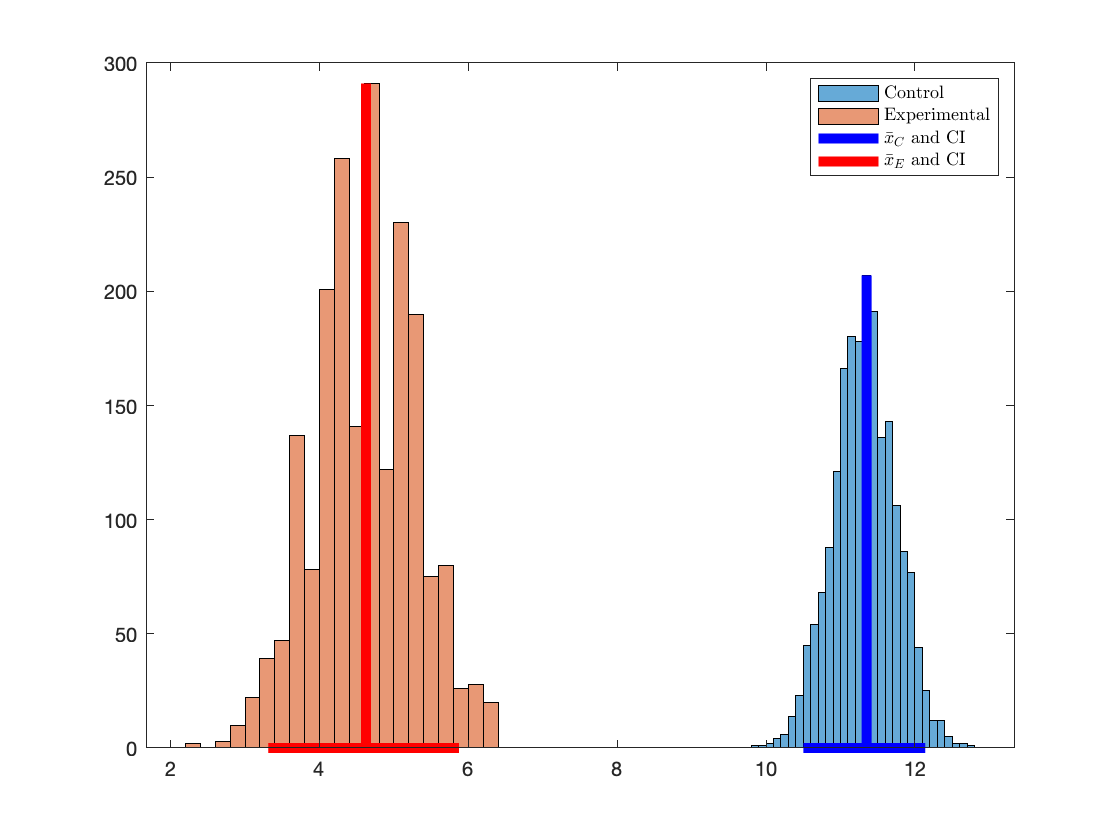


hc=histogram(Mc+xbar-zbar);
hold on 
he=histogram(Me+ybar-zbar);
plot(CIc,[0,0],'b','LineWidth',5)
plot(CIe,[0,0],'r','LineWidth',5)
plot([xbar xbar],[0,max(hc.BinCounts)],'b',"LineWidth",5)
plot([ybar ybar],[0,max(he.BinCounts)],'r',"LineWidth",5)
legend('Control','Experimental','$\bar{x}_C$ and CI', '$\bar{x}_E$ and CI','interpreter','latex')
hold off

The means of the control and experimental data sets are well separated and their 95% confidence intervals don't overlap at all. This already indicates that there is a significant difference between the two means. However, we can also employ more quantitative methods of determining if they are significantly different. Since we have a bootstrapped data set of two-sample t statistics, we can perform the analog of a two sample t test by computing the Achieved Significance Level (ASL) for testing whether t is significantly different than 0. The ASL value, which represents the percentage of bootstrapped t statistics for which $t\ge t_0$  (here, $t_0$ is the t statistic for the experimental and control sample means) in lieu of the p-value from the corresponding t-test.

ASL=sum(t>=t0)/B

ASL = 0

This value is 0, which indicates that we should expect to regularly see a significant difference between the means of our control and experimental means when replicating our experiment. 